# Test CSINet in MATLAB

This live script tests pre-trained CSINet proposed in [Chao-Kai Wen, Wan-Ting Shih, and Shi Jin, "Deep learning for massive MIMO CSI feedback,” IEEE Wireless Communications Letters, 2018](https://ieeexplore.ieee.org/document/8322184/) using MATLAB®.

## Set network parameters

maxDelay = 32;
nTx = 32;
numChannels = 2;
compressRate = 1/4; % 1/4 | 1/16 | 1/32 | 1/64
environment = "indoor"; % "indoor" | "outdoor"

% Load CSINet from saved MAT files
load(fullfile("MATLAB","model_CsiNet_"+environment+"_dim"+num2str(maxDelay*nTx*numChannels*compressRate)+".mat"));

% Analyze CSINet architecture visually
analyzeNetwork(CSINet);

## Load testing data

% Load truncated channel coefficient matrices
load(fullfile("data","DATA_Htest"+extractBefore(environment,"door")+".mat"));

% Load untruncated channel coefficient matrices
load(fullfile("data","DATA_HtestF"+extractBefore(environment,"door")+"_all.mat"));
testSampleSize = length(HT);

## Test pre-trained CSInet

xTest = reshape(HT', maxDelay, nTx, numChannels, testSampleSize);
xTest = permute(xTest, [2, 1, 3, 4]);
xHat = predict(CSINet, xTest);

% Construct complex data from 2-channel input
xTestr = HT(:, 1:1024);
xTesti = HT(:, 1024 + 1:end);
xTestc = complex(xTestr - 0.5, xTesti - 0.5);

% Construct complex estimated data from 2-channel input
xHatc = complex(xHat(:, :, 1, :) - 0.5, xHat(:, :, 2, :) - 0.5);
xHatc = reshape(xHatc, nTx, maxDelay, testSampleSize);

% Apply fft to the estimated complex channel matrix to construct the
% frequency domain channel matrix
xHatFreq = fft(cat(2, xHatc, zeros(nTx, 256-maxDelay, testSampleSize)), [], 2);
xHatFreq = xHatFreq(:, 1:125, :);

% Calculate the cosine similarity of channel matrices in frequency-spatial
% domain
xtestFreq = reshape(HF_all.', 125, nTx, testSampleSize);
xtestFreq = permute(xtestFreq, [2, 1, 3]);
n1 = squeeze(sqrt(sum(conj(xtestFreq).*xtestFreq, 1)));
n2 = squeeze(sqrt(sum(conj(xHatFreq).*xHatFreq, 1)));
aa = squeeze(abs(sum(conj(xtestFreq).*xHatFreq, 1)));
rho = aa./(n1.*n2);
[~, idxMax] = max(mean(rho, 1));
[~, idxMin] = min(mean(rho, 1));
meanRho = mean(rho, 'All');
fprintf("\nAt compression rate 1/%d, rho is %f\n",1/compressRate, meanRho);


At compression rate 1/4, rho is 0.993161



% Calculate MSE between test & predicted channel matrices in angular-delay domain
power = sum(abs(xTestc).^2, 2);
nmse = 10.*log10(squeeze(sum(abs(xTest - xHat).^2, [1,2,3]))./power);
meanMSE = mean(nmse);
fprintf("\nAt compression rate 1/%d, nmse is %f\n",1/compressRate, meanMSE);


At compression rate 1/4, nmse is -21.500923


## Plot the channel matrix before and after compression for the max value of rho

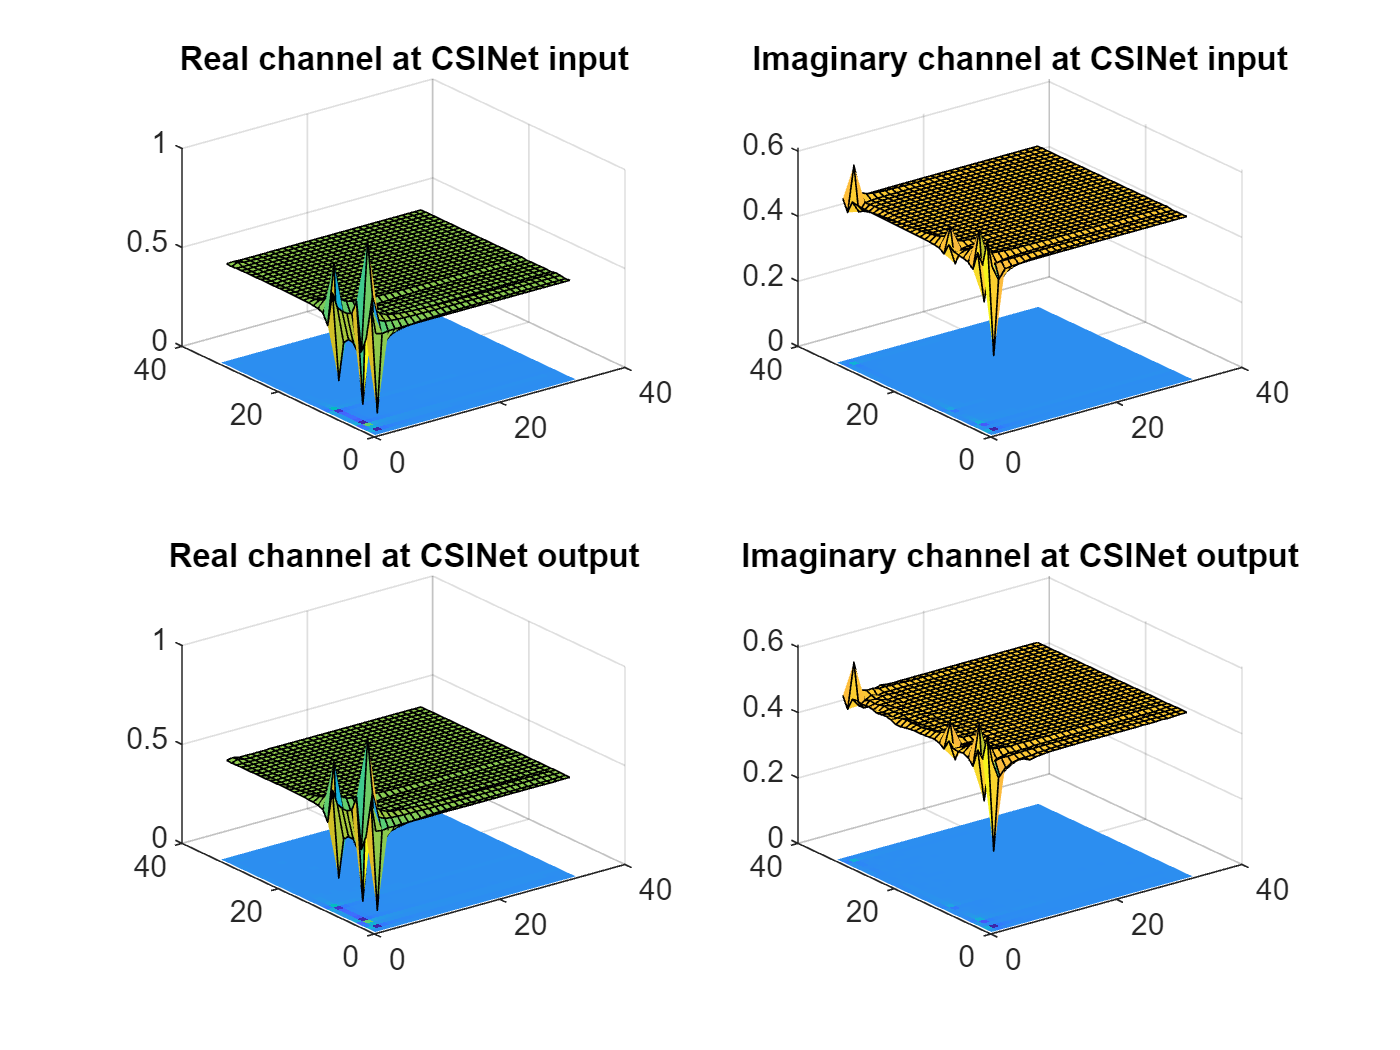

subplot(2,2,1)
surf(xTest(:,:,1,idxMax))
hold on
imagesc(xTest(:,:,1,idxMax)-0.5)
title("Real channel at CSINet input")

subplot(2,2,2)
surf(xTest(:,:,2,idxMax))
hold on
imagesc(xTest(:,:,2,idxMax)-0.5)
title("Imaginary channel at CSINet input")

subplot(2,2,3)
surf(xHat(:,:,1,idxMax))
hold on
imagesc(xHat(:,:,1,idxMax)-0.5)
title("Real channel at CSINet output")

subplot(2,2,4)
surf(xHat(:,:,2,idxMax))
hold on
imagesc(xHat(:,:,2,idxMax)-0.5)
title("Imaginary channel at CSINet output")

## Plot the channel matrix before and after compression for the min value of rho

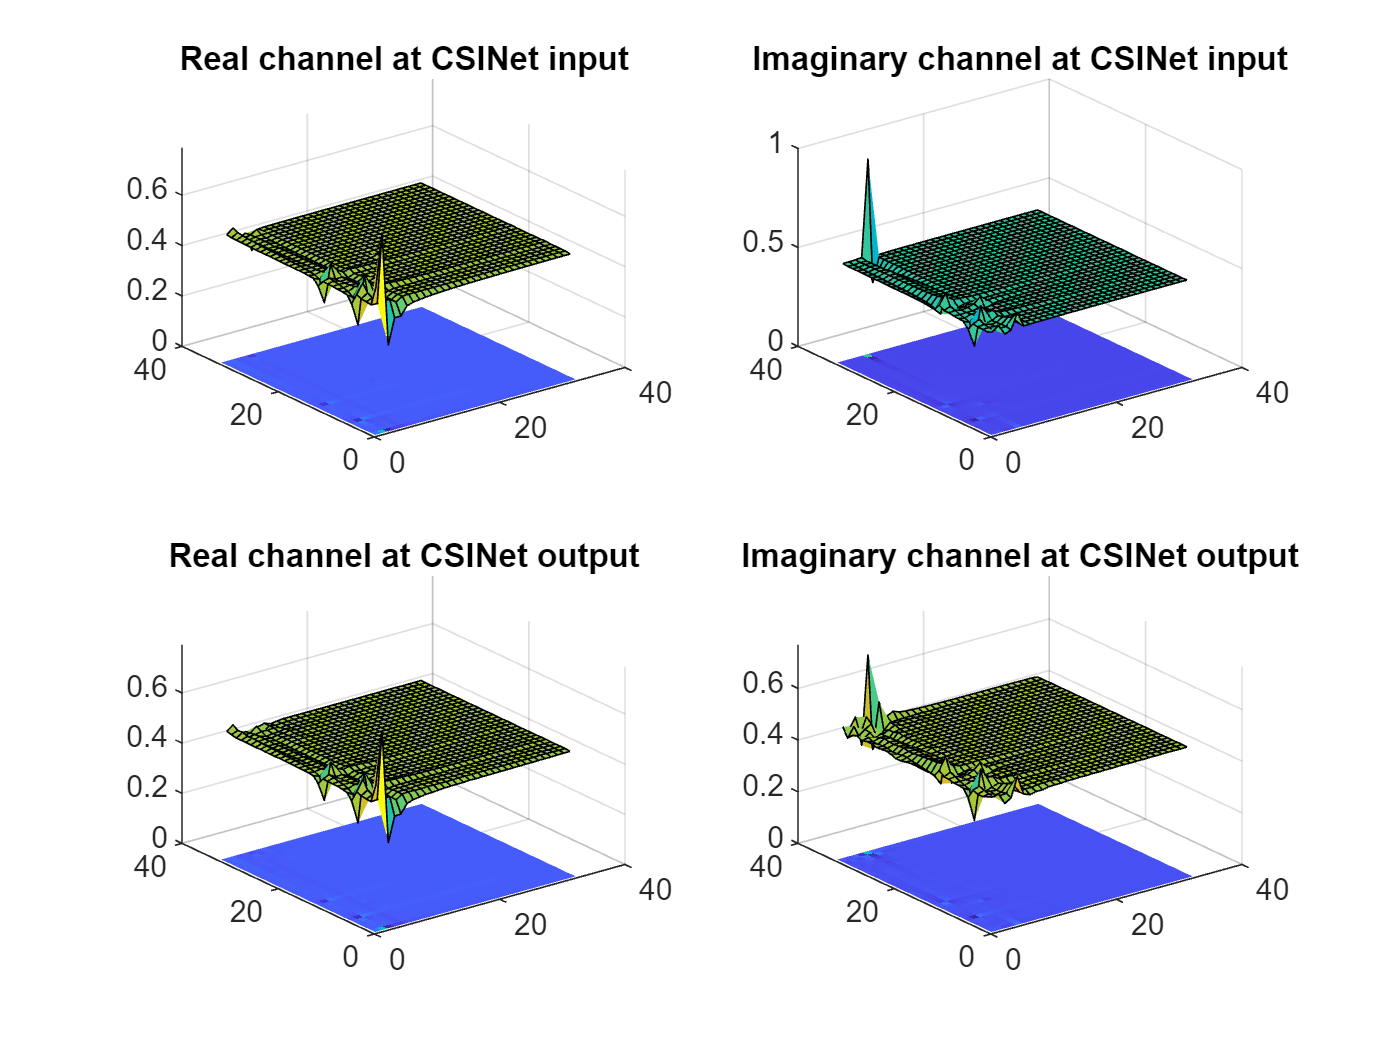

figure(2)
subplot(2,2,1)
surf(xTest(:,:,1,idxMin))
hold on
imagesc(xTest(:,:,1,idxMin)-0.5)
title("Real channel at CSINet input")

subplot(2,2,2)
surf(xTest(:,:,2,idxMin))
hold on
imagesc(xTest(:,:,2,idxMin)-0.5)
title("Imaginary channel at CSINet input")

subplot(2,2,3)
surf(xHat(:,:,1,idxMin))
hold on
imagesc(xHat(:,:,1,idxMin)-0.5)
title("Real channel at CSINet output")

subplot(2,2,4)
surf(xHat(:,:,2,idxMin))
hold on
imagesc(xHat(:,:,2,idxMin)-0.5)
title("Imaginary channel at CSINet output")